addpath(genpath('~/Documents'));

%% Create bone structure 
% bones = {{'227G' 1270 1793}; {'245D' 470 1861}; {'251G' 761 2125}; {'271G' 1590 2954}};
bones = {'271G' '267G' '251G' '245D' '227G'};
min_slices = [1270 0 470 761 1590];
max_slices = [1793 0 1861 2125 2954];
T = table(min_slices', max_slices', 'VariableNames', {'min_slice', 'max_slice'}, 'RowNames', bones);

% Get bone

`Select the bone : `

bone = '227G';
dirname = ['~/Documents/BoneRugosity/RMS/', bone, '/'];

min_slice = T{bone, 'min_slice'};
max_slice = T{bone, 'max_slice'};

`Select the slice :`

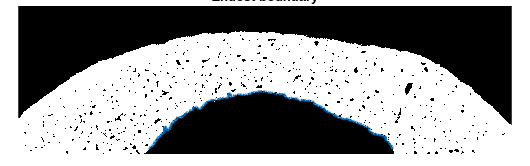

num_slice = 1590;

file = ['SAMPLE_', bone, '_SLICE_', int2str(num_slice), '.bmp']; 
filename = [dirname, file];

% Load image
bone_bmp = imread(filename); 

%% INITIAL COMPUTATION OF RMS HEIGTH
% THRESHOLD TO CONVERT TO BINARY IMAGE
threshold = graythresh(bone_bmp); % Find an automatic threshold
binary_image = imbinarize(bone_bmp, threshold);

% BOUNDARIES COMPUTATION
boundary_endost = ExtractBoundary(binary_image);
figure
imshow(binary_image);
hold on;
plot(boundary_endost(1, :), boundary_endost(2, :), 'LineWidth', 2);  
hold on;
xlabel('Width');
ylabel('Depth');
title('Endost boundary'); hold off;

boundary_endost(2, :) = max(boundary_endost(2, :)) - boundary_endost(2, :);

%% COMPUTE FOURRIER TRANSFORM OF THE PROFILE
% Parameters
delta_x = 9e-3;             % Pixel size corresponding to the space step (mm)
Fs = 1/delta_x;             % Sampling frequency (mm-1)
L = size(boundary_endost, 2);

% Initial profile
profile = boundary_endost(2, 2:end) * delta_x; % - mean(boundary_endost(2, :));

x = (0:L-1)*1/Fs;

%% WITH BUILT-IN FUNCTION 

Select the cut off frequency 

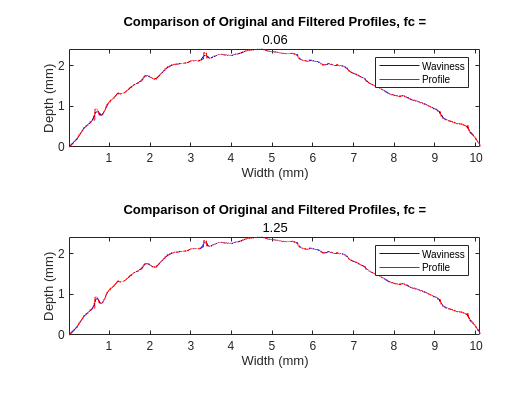

fc = 0.06;
waviness = lowpass(profile,fc,Fs);
roughness = highpass(profile, fc, Fs);

figure
subplot(2,1,1)
plot(x(1, 2:end), real(waviness), 'b', 'DisplayName', 'Waviness');
hold on
plot(x(1, 2:end), profile, 'r', 'DisplayName', 'Profile');
title('Comparison of Original and Filtered Profiles, fc =', fc);
xlabel('Width (mm)');
ylabel('Depth (mm)');
legend();
hold off
axis image
subplot(2,1,2)
plot(x(1, 2:end), real(lowpass(profile,1.25,Fs)), 'b', 'DisplayName', 'Waviness');
hold on
plot(x(1, 2:end), profile, 'r', 'DisplayName', 'Profile');
title('Comparison of Original and Filtered Profiles, fc =', 1.25);
xlabel('Width (mm)');
ylabel('Depth (mm)');
legend();
hold off
axis image

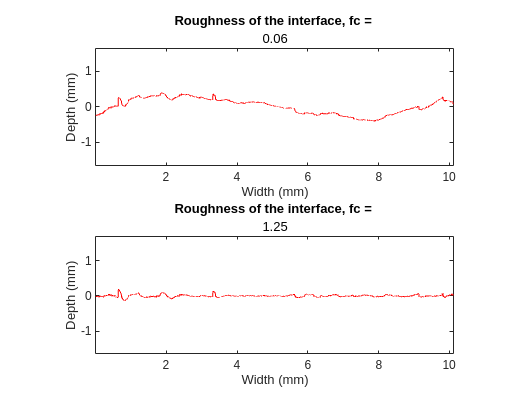

figure
subplot(2,1,1)
plot(x(1, 2:end), roughness, 'r');
title('Roughness of the interface, fc = ', fc);
xlabel('Width (mm)');
ylabel('Depth (mm)');
axis equal
subplot(2,1,2)
plot(x(1, 2:end), highpass(profile, 1.25, Fs), 'r');
title('Roughness of the interface, fc = ', 1.25);
xlabel('Width (mm)');
ylabel('Depth (mm)');
axis equal

rms_fc = rms(roughness);
rms_8 = rms(highpass(profile, 1.25, Fs));
fprintf('With fc = 0.06mm-1, Rms = %.2f um \nWith fc = 1.25mm-1, Rms = %.2f um', rms_fc*1e3, rms_8*1e3);

With fc = 0.06mm-1, Rms = 219.25 um 
With fc = 1.25mm-1, Rms = 33.14 um

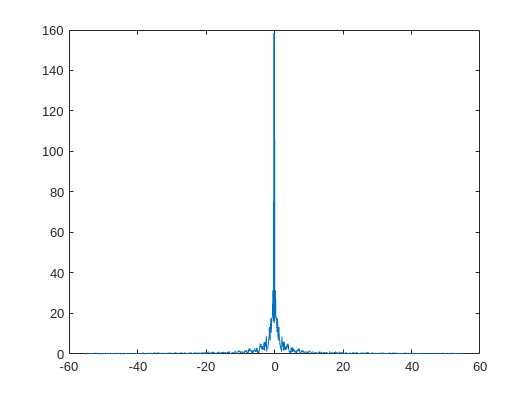

fft_rough = fft(roughness);
figure
plot(f(1:end-1), fftshift(abs(fft_rough)));

w = highpass(profile, 0.06, Fs);
save(fullfile(simu_dir, 'waviness.mat'), w);
r = highpass(profile, 1.25, Fs);
save(fullfile(simu_dir, 'rougness.mat'), r);

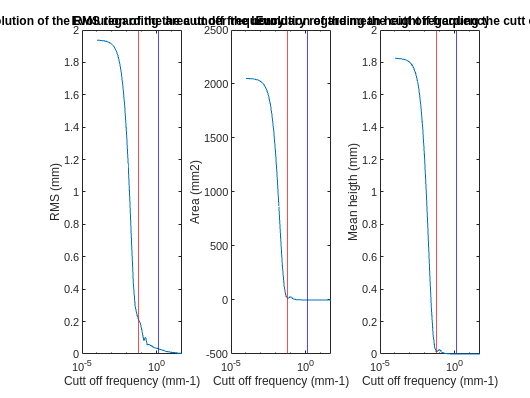

frequencies = logspace(log10(1e-4), log10(50), 50);
parameters = zeros(3, length(frequencies));
% figure 
for i = 1 : length(frequencies)
    [roughness] = GetRoughness(bone_bmp, frequencies(i));
    parameters(1, i) = rms(roughness);
    parameters(2, i) = trapz(roughness);
    parameters(3, i) = mean(roughness);
    
    % plot(x(2:end), real(lowpass(profile, frequencies(i), Fs)), 'b', 'DisplayName', 'Waviness');
    % hold on
    % plot(x(2:end), profile, 'r', 'DisplayName', 'Profile');
    % title('Comparison of Original and Filtered Profiles, fc =', frequencies(i));
    % xlabel('Width (mm)');
    % ylabel('Depth (mm)');
    % legend();
    % hold off
    % axis image
    % pause(0.2)

end
figure
subplot(1,3,1)
semilogx(frequencies, parameters(1, :));
hold on 
xline(fc, 'r');
xline(1.25, 'b');
hold off
title('Evolution of the RMS regarding the cutt off frequency');
xlabel('Cutt off frequency (mm-1)');
ylabel('RMS (mm)');

subplot(1,3,2)
semilogx(frequencies, parameters(2, :));
hold on 
xline(fc, 'r');
xline(1.25, 'b');
hold off
title('Evolution of the area under the boundary regarding the cutt off frequency');
ylabel('Area (mm2)');
xlabel('Cutt off frequency (mm-1)');

subplot(1,3,3)
semilogx(frequencies, parameters(3, :));
hold on 
xline(fc, 'r');
xline(1.25, 'b');
hold off
title('Evolution of the mean height regarding the cutt off frequency');
ylabel('Mean heigth (mm)');
xlabel('Cutt off frequency (mm-1)');